f = @(w) 0.4 .* w.^2 + 4 .* w + 11;

W = linspace(-20,20,1000);

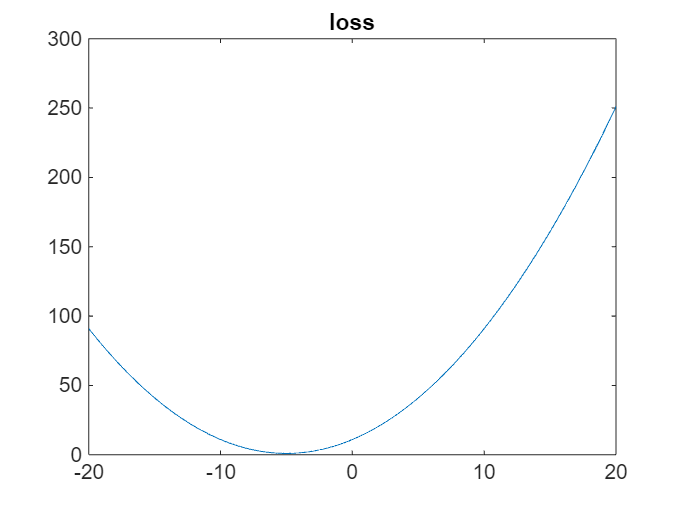

plot(W,f(W))
title("loss")

df = @(w) 0.8 .* w + 4;
d2f = @(w) 0.8 ;

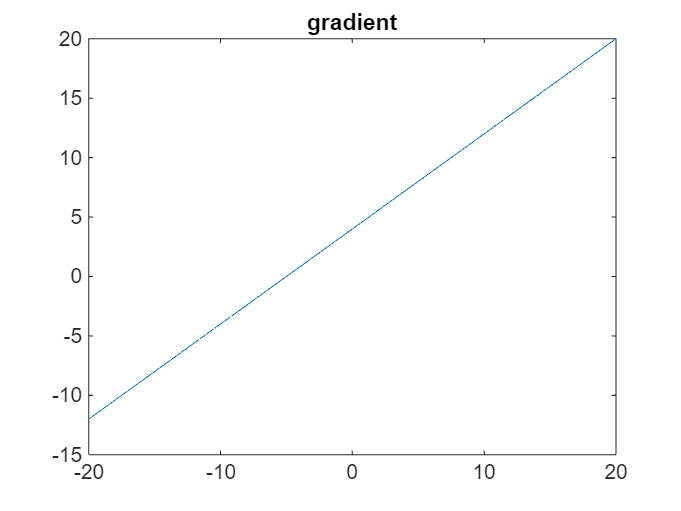

plot(W,df(W))
title("gradient")

function w = SD(w0, mu, df, eps)
    max_iter = 1000;
    w = zeros(1, max_iter); 
    
    % Initialize
    w(1) = w0;
    k = 1;
    converged = false;

    while (k < max_iter)
        % 2. Calculate the next step (Minimization is '-' mu * df)
        gradient = df(w(k));
        next_w = w(k) - mu * gradient;
        
        % 3. Check for convergence BEFORE assigning to the array
        if abs(next_w - w(k)) < eps
            w(k+1) = next_w;
            k = k + 1;
            converged = true;
            break; 
        end
        
        % Store and increment
        w(k+1) = next_w;
        k = k + 1;
    end
    w = w(1:k);
    
    if ~converged
        warning('Algorithm reached max iterations without converging.');
    end
end

w0=0;
mu = 1.5;
eps = 1e-5;
w_SD = SD(w0,mu,df,eps)

w_SD =          0   -6.0000   -4.8000   -5.0400   -4.9920   -5.0016   -4.9997   -5.0001   -5.0000   -5.0000   -5.0000


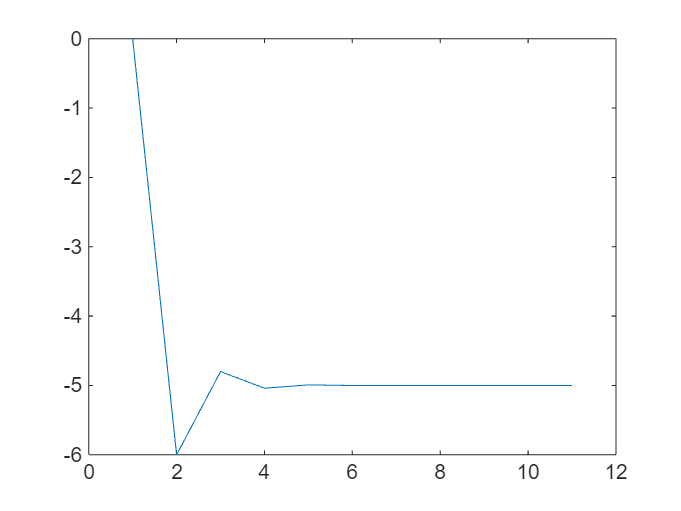

plot(1:length(w_SD),w_SD)

function w = Newton(w0, df, d2f, eps)
    max_iter = 1000;
    w = zeros(1, max_iter); 
    
    % Initialize
    w(1) = w0;
    k = 1;
    converged = false;

    while (k < max_iter)
        % 2. Calculate the next step 
        next_w = w(k) - df(w(k))/d2f(w(k));
        
        % 3. Check for convergence BEFORE assigning to the array
        if abs(next_w - w(k)) < eps
            w(k+1) = next_w;
            k = k + 1;
            converged = true;
            break; 
        end
        
        % Store and increment
        w(k+1) = next_w;
        k = k + 1;
    end
    w = w(1:k);
    
    if ~converged
        warning('Algorithm reached max iterations without converging.');
    end
end

w0 = 0;
mu = 1.5;
eps = 1e-5;

w_Newton = Newton(w0,df,d2f,eps)

w_Newton =      0    -5    -5


w_SD= SD(w0,mu,df,eps)

w_SD =          0   -6.0000   -4.8000   -5.0400   -4.9920   -5.0016   -4.9997   -5.0001   -5.0000   -5.0000   -5.0000


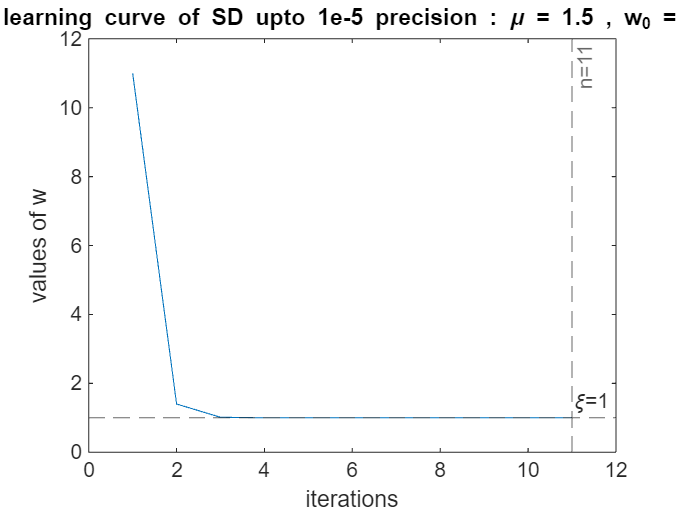

plot(1:length(w_SD),f(w_SD))
title("learning curve of SD upto 1e-5 precision : \mu = 1.5 , w_0 = 0")
xlabel("iterations")
ylabel("values of w")
yline(1,'--',"\xi=1")
xline(11,'--',"n=11")

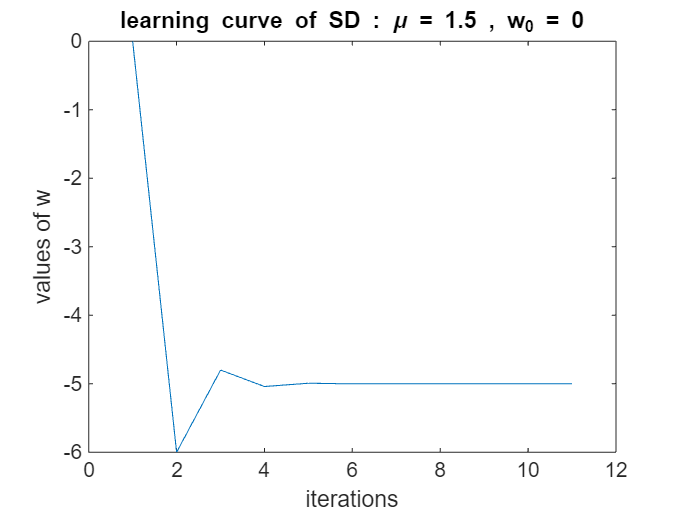


plot(1:length(w_SD),w_SD)
title("learning curve of SD : \mu = 1.5 , w_0 = 0")
xlabel("iterations")
ylabel("values of w")

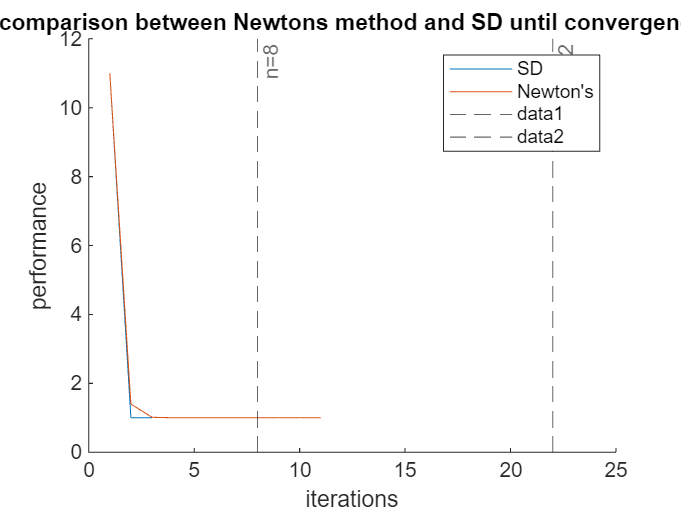

figure;
hold on ;

plot(1:length(w_Newton),f(w_Newton))
plot(1:length(w_SD),f(w_SD))

legend("SD","Newton's")
title("comparison between Newtons method and SD until convergence")
xlabel("iterations")
ylabel("performance")
xline(8,"--","n=8")
xline(22,"--","n=22")
hold off ; 

**2.g**

mu = 0.05;
w0 = 0;

g = @(w) 42 + w' * [[2,1];[1,2]] * w - 2 * [7;8]' * w ;

dg = @(w) 2 * [[2,1];[1,2]] * w - 2 * [7;8] ;

d2g = @(w) 2 * [[2,1];[1,2]] ;

% Wrap the function to apply it to each column of the input matrix
g_vec = @(W) arrayfun(@(i) g(W(:,i)), 1:size(W,2));

% Test it:
result = g_vec(zeros(2,5)) % Returns: [42, 42, 42, 42, 42]

result =     42    42    42    42    42


we rewrite the equation to support matrices :

function w = Newton_M(w0, df, d2f, mu, eps)
    max_iter = 1000;
    
    % Ensure w0 is a column vector for consistency
    w0 = w0(:); 
    dim = length(w0);
    
    % Preallocate: rows = dimensions, columns = iterations
    w = zeros(dim, max_iter); 
    
    % Initialize
    w(:, 1) = w0;
    k = 1;
    converged = false;

    while (k < max_iter)
        current_w = w(:, k);
        
        % Calculate the next step using the backslash operator
        % Works for Matrix (Hessian \ Gradient) and Scalar (f'' \ f')
        step = d2f(current_w) \ df(current_w);
        next_w = current_w - mu*step;
        
        % Check for convergence using the norm (magnitude of the step)
        if norm(next_w - current_w) < eps
            w(:, k+1) = next_w;
            k = k + 1;
            converged = true;
            break; 
        end
        
        % Store and increment
        w(:, k+1) = next_w;
        k = k + 1;
    end
    
    % Trim unused preallocated columns
    w = w(:, 1:k);
    
    if ~converged
        warning('Algorithm reached max iterations without converging.');
    end
end

function w = SD_M(w0, mu, df, eps)
    max_iter = 1000;
    
    % Ensure w0 is a column vector
    w0 = w0(:);
    dim = length(w0);
    
    % Preallocate: rows = dimensions, columns = iterations
    w = zeros(dim, max_iter); 
    
    % Initialize
    w(:, 1) = w0;
    k = 1;
    converged = false;

    while (k < max_iter)
        current_w = w(:, k);
        
        % 2. Calculate the next step (Gradient Descent)
        gradient = df(current_w);
        next_w = current_w - mu * gradient;
        
        % 3. Check for convergence using the norm of the step
        if norm(next_w - current_w) < eps
            w(:, k+1) = next_w;
            k = k + 1;
            converged = true;
            break; 
        end
        
        % Store and increment
        w(:, k+1) = next_w;
        k = k + 1;
    end
    
    % Trim unused columns
    w = w(:, 1:k);
    
    if ~converged
        warning('Algorithm reached max iterations without converging.');
    end
end

w0 = [0;0];
mu = 0.05;
eps = 1e-6;
w_Newton_M = Newton_M(w0, dg, d2g,mu, eps);
w_SD_M = SD_M(w0, mu, df, eps)

w_SD_M =          0   -0.2000   -0.3920   -0.5763   -0.7533   -0.9231   -1.0862   -1.2428   -1.3931   -1.5373   -1.6758   -1.8088   -1.9365   -2.0590   -2.1766   -2.2896   -2.3980   -2.5021   -2.6020   -2.6979   -2.7900   -2.8784   -2.9633   -3.0447   -3.1229   -3.1980   -3.2701   -3.3393   -3.4057   -3.4695   -3.5307   -3.5895   -3.6459   -3.7001   -3.7521   -3.8020   -3.8499   -3.8959   -3.9401   -3.9825   -4.0232   -4.0622   -4.0998   -4.1358   -4.1703   -4.2035   -4.2354   -4.2660   -4.2953   -4.3235
         0   -0.2000   -0.3920   -0.5763   -0.7533   -0.9231   -1.0862   -1.2428   -1.3931   -1.5373   -1.6758   -1.8088   -1.9365   -2.0590   -2.1766   -2.2896   -2.3980   -2.5021   -2.6020   -2.6979   -2.7900   -2.8784   -2.9633   -3.0447   -3.1229   -3.1980   -3.2701   -3.3393   -3.4057   -3.4695   -3.5307   -3.5895   -3.6459   -3.7001   -3.7521   -3.8020   -3.8499   -3.8959   -3.9401   -3.9825   -4.0232   -4.0622   -4.0998   -4.1358   -4.1703   -4.2035   -4.2354   -4.2660   -4.2953

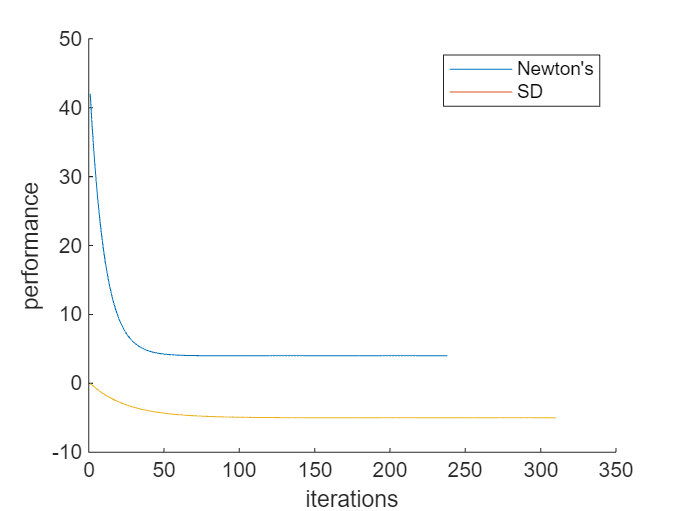

figure;
hold on;

plot(1:length(w_Newton_M),g_vec(w_Newton_M));
plot(1:length(w_SD_M),w_SD_M);

xlabel("iterations")
ylabel("performance")
legend("Newton's",'SD')
hold off;

f1 = @(k) 4 + 0.5 .* (0.9).^(2.*k) + 12.5 .* (0.7).^(2.*k);
f2 = @(k) 4 + 38 .* (0.9).^(2.*k);
K = 1:25;
F1 = f1(K);
F2 = f2(K)

F2 =    34.7800   28.9318   24.1948   20.3578   17.2498   14.7323   12.6932   11.0415    9.7036    8.6199    7.7421    7.0311    6.4552    5.9887    5.6109    5.3048    5.0569    4.8561    4.6934    4.5617    4.4550    4.3685    4.2985    4.2418    4.1958


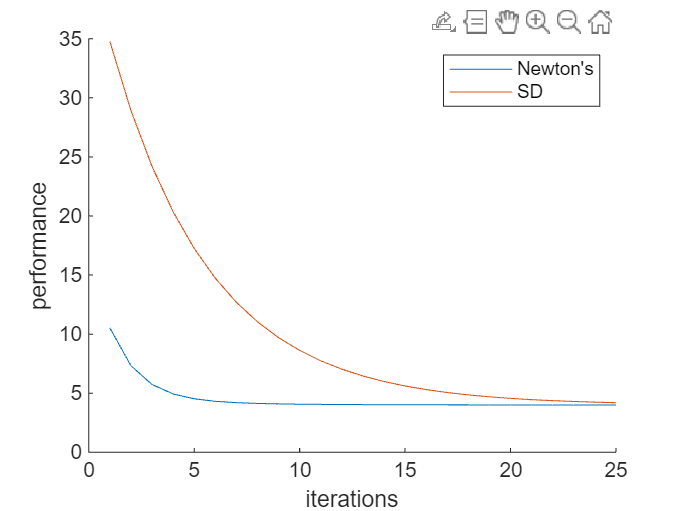


figure;
hold on ;

plot(K,F1(K))
plot(K,F2(K))

xlabel("iterations")
ylabel("performance")
legend("Newton's",'SD')

hold off ;

**3.b**

p = @(x) 5.*x.^2 -20.*x + 23 

p = function_handle with value:
    @(x)5.*x.^2-20.*x+23



x1 = 2.5;
p1 = p(x1)

p1 = 4.2500


x2 = 1.5;
p2 = p(x2)

p2 = 4.2500


x3 = 3.5;
p3 = p(x3)

p3 = 14.2500


l1 = @(x) 4.25 + (x-2.5).*5

l1 = function_handle with value:
    @(x)4.25+(x-2.5).*5


l2 = @(x) 5 + 4.25 + (x-2.5).*5

l2 = function_handle with value:
    @(x)5+4.25+(x-2.5).*5


X = linspace(0,4,1000)

X =          0    0.0040    0.0080    0.0120    0.0160    0.0200    0.0240    0.0280    0.0320    0.0360    0.0400    0.0440    0.0480    0.0521    0.0561    0.0601    0.0641    0.0681    0.0721    0.0761    0.0801    0.0841    0.0881    0.0921    0.0961    0.1001    0.1041    0.1081    0.1121    0.1161    0.1201    0.1241    0.1281    0.1321    0.1361    0.1401    0.1441    0.1481    0.1522    0.1562    0.1602    0.1642    0.1682    0.1722    0.1762    0.1802    0.1842    0.1882    0.1922    0.1962


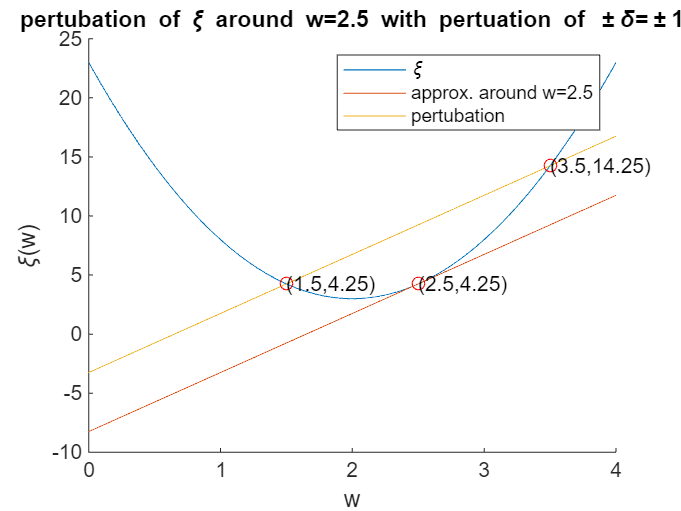

figure; 
hold on ; 

plot(X,p(X))
plot(X,l1(X))
plot(X,l2(X))
plot(x1,p1,"or")
text(x1, p1, '(2.5,4.25)')
plot(x2,p2,"or")
text(x2, p2, '(1.5,4.25)')
plot(x3,p3,"or")
text(x3, p3, '(3.5,14.25)')
legend("\xi","approx. around w=2.5","pertubation")
xlabel("w")
ylabel("\xi(w)")

title("pertubation of \xi around w=2.5 with pertuation of \pm\delta=\pm1")
hold off ;